# EXAMPLES OF CATEGORICAL DATA ANALYSIS

examples_categorical shows a series of analysis of correspondence analysis datasets Copyright 2008-2019. Written by FSDA team

%$LastChangedDate::                      $: Date of the last commit

## Beginning of code

## Correpondence analysis of the smoke data (1)

Input is the contingency table In this case we load data from the txt file which contains the codifed labels 

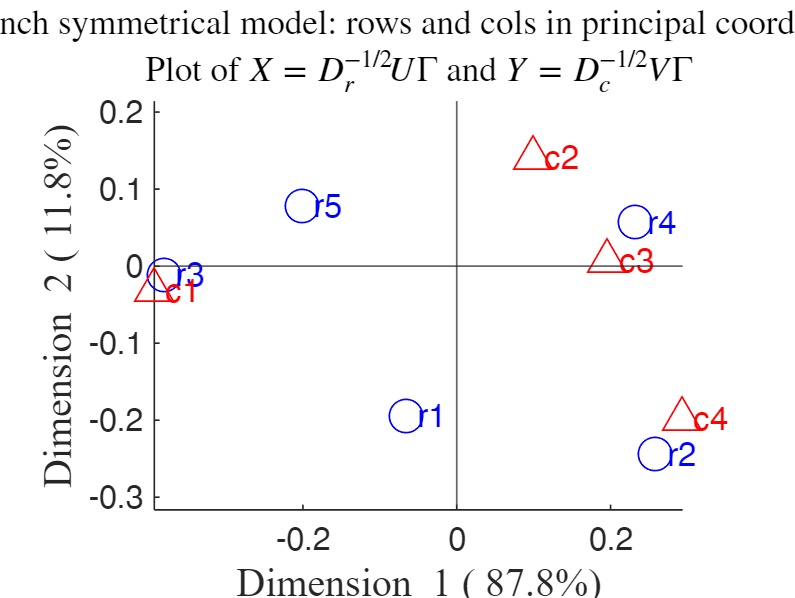

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
           Scores      CntrbPnt2In    CntrbDim2In
          _________    ___________    ___________

    r1    -0.065768     0.0032977      0.092232  
    r2      0.25896      0.083659        0.5264  
    r3     -0.38059       0.51201       0.99903 

X=load('smoke.txt');
N=crosstab(X(:,1),X(:,2));
% All rows and columns of n are active points (no supplementary unit)
out=CorAna(N);

## Correpondence analysis of the smoke data (2)

In this case we load the data in table format

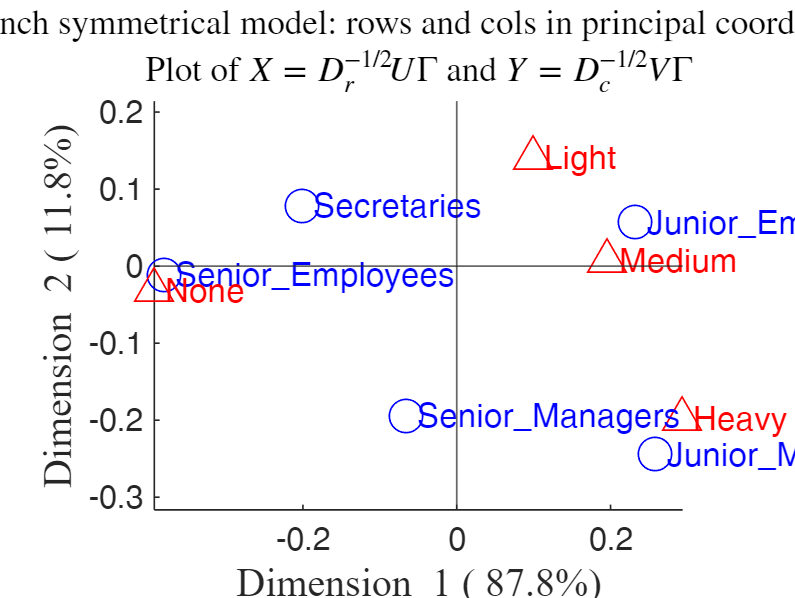

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
                         Scores      CntrbPnt2In    CntrbDim2In
                        _________    ___________    ___________

    Senior_Managers     -0.065768     0.0032977      0.092232  
    Junior_Managers       0.25896      0.083659        0.5264  
    

load('smoke');
% X is a cell array of size 193-by-2 which contains the two variables
X=smoke{:,1:2};
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);
% Input is the contingency table, labels for rows and columns are supplied
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns);

## Correpondence analysis of the smoke data (3)

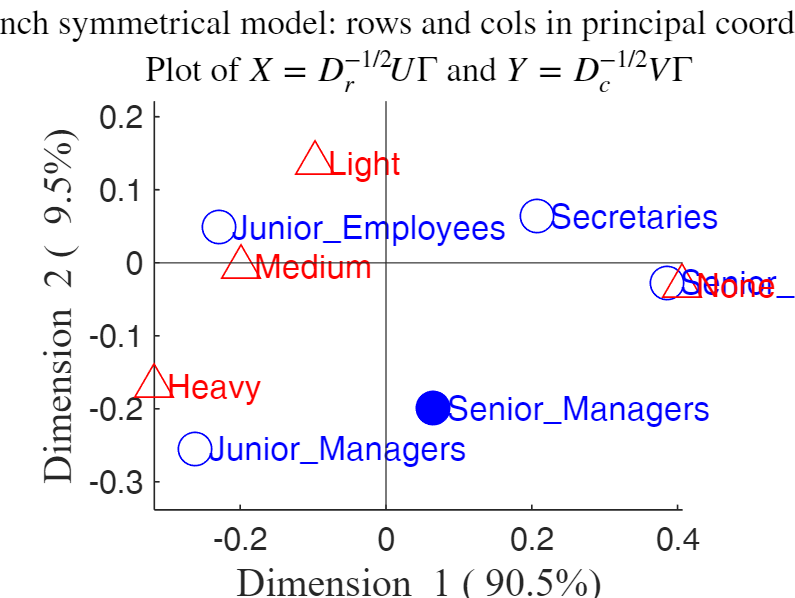

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.28222        0.079648        0.90507       0.90507  
    dim_2       0.091295       0.0083348       0.094713       0.99978  
    dim_3      0.0043578       1.899e-05     0.00021579             1  

ROW POINTS
Results for dimension: 1
                         Scores     CntrbPnt2In    CntrbDim2In
                        ________    ___________    ___________

    Junior_Managers     -0.26068     0.084381        0.51272  
    Senior_Employees     0.38561      0.52315        0.99506  
    Junior

load('smoke');
% X is a cell array of size 193-by-2 which contains the two variables
X=smoke{:,1:2};
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);

% Input is the contingency table, first row is used as supplementary point
% In this case the list of supplementary units is passed using field .r
% passed as non negative number  which identifies  the row to use as
% supplementary point.
Sup=struct;
Sup.r=1;
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (4)

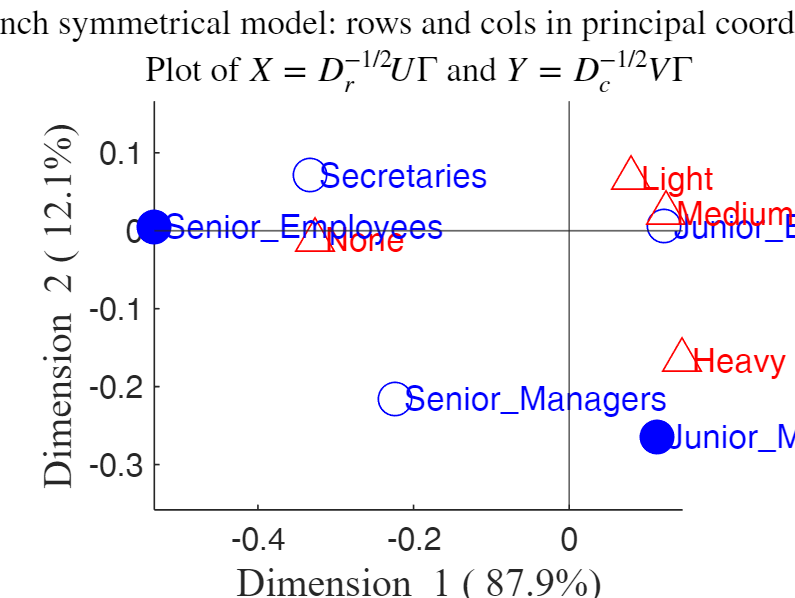

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.19347        0.037432       0.8789          0.8789  
    dim_2       0.071818       0.0051578       0.1211               1  

ROW POINTS
Results for dimension: 1
                         Scores     CntrbPnt2In    CntrbDim2In
                        ________    ___________    ___________

    Senior_Managers     -0.22366      0.11855        0.52045  
    Junior_Employees     0.12253      0.28462        0.99725  
    Secretaries         -0.33288      0.59683        0.95553  

Results for dimension: 2
 

load('smoke');
% X is a cell array of size 193-by-2 which contains the two variables
X=smoke{:,1:2};
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);

% Input is the contingency table, rows 2 and 3 are used as supplementary
% points.
% In this case the list of supplementary units is passed using field .r
% passed as vector of non negative numbers
Sup=struct;
Sup.r=[2,3];
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (5)

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.19347        0.037432       0.8789          0.8789  
    dim_2       0.071818       0.0051578       0.1211               1  

ROW POINTS
Results for dimension: 1
                         Scores     CntrbPnt2In    CntrbDim2In
                        ________    ___________    ___________

    Senior_Managers     -0.22366      0.11855        0.52045  
    Junior_Employees     0.12253      0.28462        0.99725  
    Secretaries         -0.33288      0.59683        0.95553  

Results for dimension: 2
 

load('smoke');
% X is a cell array of size 193-by-2 which contains the two variables
X=smoke{:,1:2};
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);

% Input is the contingency table, 2 rows are used as supplementary poitns.
% In this case the list of supplementary units is passed using field .r
% passed as a cell of characters.
Sup=struct;
Sup.r=labels_rows(2:3);
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'Sup',Sup);

## Correpondence analysis of the smoke data (6)

The input is the original data matrix.

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
                         Scores      CntrbPnt2In    CntrbDim2In
                        _________    ___________    ___________

    Senior_Managers     -0.065768     0.0032977      0.092232  
    Junior_Managers       0.25896      0.083659        0.5264  
    

load('smoke');
% X is a cell array of size 193-by-2 which contains the two variables
X=smoke{:,1:2};
out=CorAna(X,'datamatrix',true);

## Correpondence analysis of the smoke data (7)

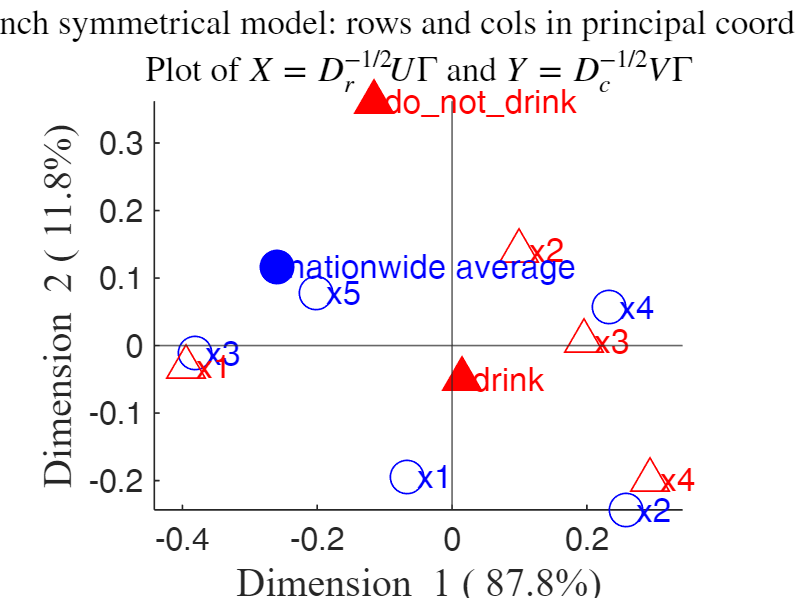

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
           Scores      CntrbPnt2In    CntrbDim2In
          _________    ___________    ___________

    x1    -0.065768     0.0032977      0.092232  
    x2      0.25896      0.083659        0.5264  
    x3     -0.38059       0.51201       0.99903 

X=load('smoke.txt');
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);

if ~verLessThan('matlab','8.3.0')
    % In this section we reproduce Figure 3.6 of Greenacre, (1984). Theory and
    % Applications of Correspondence Analysis p. 71.
    % The input is the original data matrix.
    % Supplementary rows and columns are passed as tables.
    supr=[0.42 0.29 0.20 0.09];
    Nsupr=array2table(supr,'RowNames',{'nationwide average'},'VariableNames',labels_columns);
    supc=[0 11; 1 17; 5 46; 10 78; 7 18];
    Nsupc=array2table(supc,'RowNames',labels_rows,'VariableNames',{'do_not_drink' 'drink'});
    Sup.r=Nsupr;
    Sup.c=Nsupc;
    out=CorAna(X,'Lr',labels_rows,'Lc',labels_columns,'datamatrix',true,'Sup',Sup);
else
    disp('This example runs only from MATLAB R2014A')
end

## Correpondence analysis of the smoke data (8)

In this case the input cell is passed directly to CorAna

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
                         Scores      CntrbPnt2In    CntrbDim2In
                        _________    ___________    ___________

    Senior_Managers     -0.065768     0.0032977      0.092232  
    Junior_Managers       0.25896      0.083659        0.5264  
    

ans = struct with fields:
                       Lr: [5×1 string]
                       Lc: {4×1 cell}
                        N: [5×4 double]
                   Ntable: [5×4 table]
                        I: 5
                        J: 4
                        n: 193
                     Nhat: [5×4 double]
                Nhattable: [5×4 table]
                        P: [5×4 double]
                   Ptable: [5×4 table]
                        r: [5×1 double]
                       Dr: [5×5 double]
                        c: [4×1 double]
                       Dc: [4×4 double]
             ProfilesRows: [5×4 double]
             ProfilesCols: [5×4 double]
                        K: 3
                        k: 2
                Residuals: [5×4 double]
             TotalInertia: 0.0852
                 Chi2stat: 16.4416
                  CramerV: 0.1685
         InertiaExplained: [3×4 double]
                  RowsPri: [5×3 double]
                  ColsPri: [4×3 double]
         

load smoke
CorAna(smoke{:,1:2},'datamatrix',true)

## Correpondence analysis of the smoke data (9)

In this section we explore options inside input structure plots

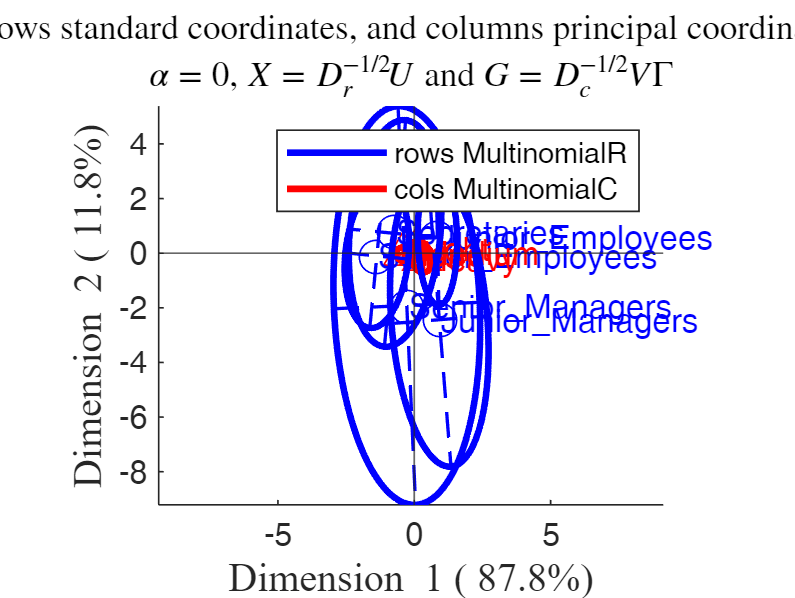

load smoke
X=smoke{:,1:2};
[N,~,~,labels]=crosstab(X(:,1),X(:,2));
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);


out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'plots',0,'dispresults',false);
plots=struct;
plots.alpha='rowgab';
plots.alpha='colgab';
plots.alpha='rowgreen';
plots.alpha='colgreen';
% Add confidence ellipses
confellipse=1;
plots.alpha='bothprincipal';
plots.alpha='rowprincipal';
plots.alpha='colprincipal';
CorAnaplot(out,'plots',plots,'confellipse',confellipse)

## Correspondence analysis of the children dataset (1)

The data used here are a contingency table that summarizes the answers given by different categories of people to the following question : according to you, what are the reasons that can make hesitate a woman or a couple to have children? The input N is a matrix with 18 rows and 8 columns. Rows represent the the different reasons mentioned, columns represent the different categories (education, age) people belong to. Active rows (rows 1:14) : Rows that are used during the correspondence analysis. Supplementary rows (rows 15:18): the coordinates of these rows will be predicted using the CA informations and parameters obtained with active rows/columns Active columns (columns 1:5): columns that are used for the correspondence analysis. Supplementary columns (6:8): the coordinates of these columns will be predicted. Source Traitements Statistiques des Enquêtes (D. Grangé, L. Lebart, eds.) Dunod, 1993

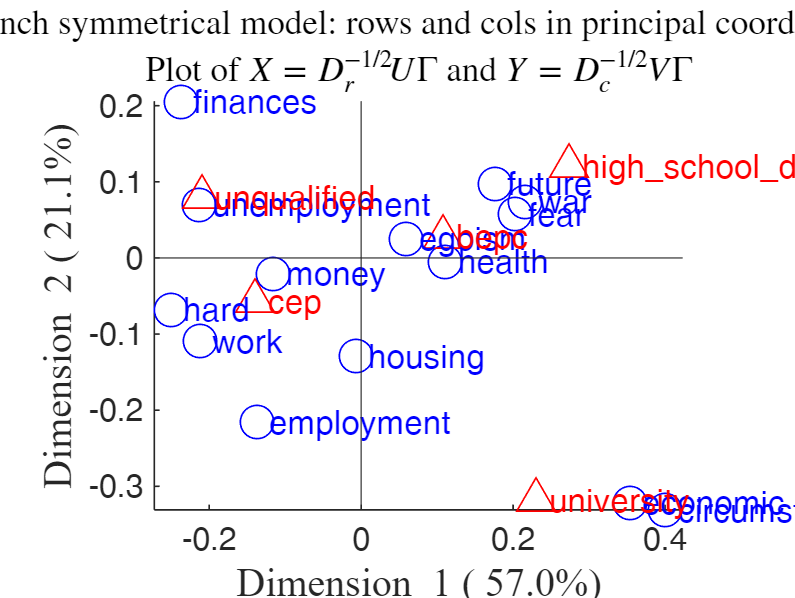

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.18815        0.035402       0.57043        0.57043  
    dim_2        0.11452        0.013115       0.21132        0.78175  
    dim_3       0.085447       0.0073011       0.11764        0.89939  
    dim_4       0.079018       0.0062439       0.10061              1  

ROW POINTS
Results for dimension: 1
                      Scores      CntrbPnt2In    CntrbDim2In
                     _________    ___________    ___________

    money             -0.11527      0.045499        0.42845 
    fut

N=[51	64	32	29	17	59	66	70;
    53	90	78	75	22	115	117	86;
    71	111	50	40	11	79	88	177;
    1	7	5	5	4	9	8	5;
    7	11	4	3	2	2	17	18;
    7	13	12	11	11	18	19	17;
    21	37	14	26	9	14	34	61;
    12	35	19	6	7	21	30	28;
    10	7	7	3	1	8	12	8;
    4	7	7	6	2	7	6	13;
    8	22	7	10	5	10	27	17;
    25	45	38	38	13	48	59	52;
    18	27	20	19	9	13	29	53;
    35	61	29	14	12	30	63	58;
    2	4	3	1	4	nan  nan	nan	  ;
    2	8	2	5	2	nan  nan	nan;
    1	5	4	6	3	nan  nan	nan;
    3	3	1	3	4	nan  nan	nan];
% rowslab = cell containing row labels
rowslab={'money','future','unemployment','circumstances',...
    'hard','economic','egoism','employment','finances',...
    'war','housing','fear','health','work','comfort','disagreement',...
    'world','to_live'};
% colslab = cell containing column labels
colslab={'unqualified','cep','bepc','high_school_diploma','university',...
    'thirty','fifty','more_fifty'};

if ~verLessThan('matlab','8.3.0')
    tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);
    % Extract just active rows
    Nactive=tableN(1:14,1:5);
    % Correspondence analysis
    out=CorAna(Nactive);
else
    Nactive=N(1:14,1:5);
    out=CorAna(Nactive,'Lr',rowslab(1:14),'Lc',colslab(1:5));
end

## Correspondence analysis of the children dataset (2)

Supplementary rows and columns are passed as table

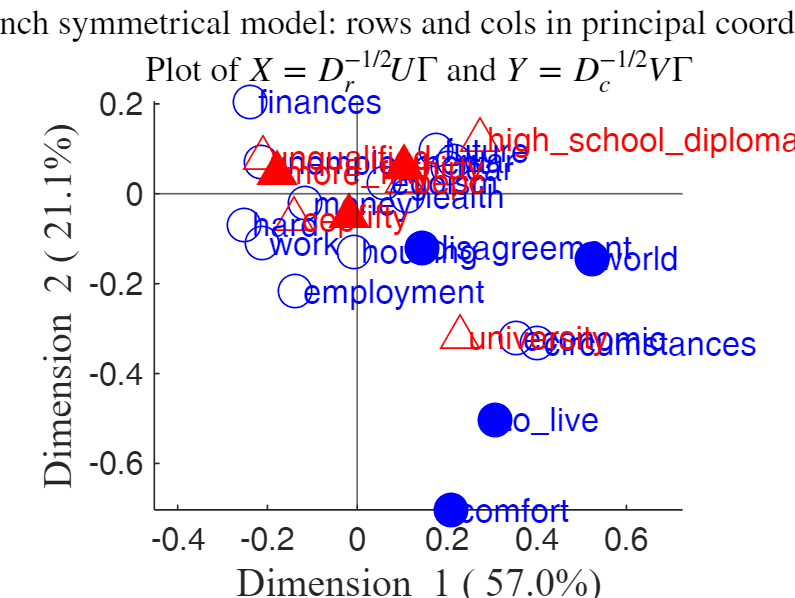

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.18815        0.035402       0.57043        0.57043  
    dim_2        0.11452        0.013115       0.21132        0.78175  
    dim_3       0.085447       0.0073011       0.11764        0.89939  
    dim_4       0.079018       0.0062439       0.10061              1  

ROW POINTS
Results for dimension: 1
                      Scores      CntrbPnt2In    CntrbDim2In
                     _________    ___________    ___________

    money             -0.11527      0.045499        0.42845 
    fut

if ~verLessThan('matlab','8.3.0')
    Nsupr=tableN(15:18,1:5);
    Nsupc=tableN(1:14,6:8);
    Sup=struct;
    Sup.r=Nsupr;
    Sup.c=Nsupc;
    out=CorAna(Nactive,'Sup',Sup);
else
    Sup=struct;
    Sup.r=N(15:18,1:5);
    Sup.c=N(1:14,6:8);
    Sup.Lr=rowslab(15:18);
    Sup.Lc=colslab(6:8);
    out=CorAna(Nactive,'Sup',Sup);
    
end

## Correspondence analysis of the housetasks dataset (1)

The data are a contingency table containing 13 housetasks and their repartition in the couple: rows are the different tasks, colums values are the frequencies of the tasks done: "by the wife only", "alternatively by the husband only" or "jointly", As the above contingency table is not very large, with a quick visual examination it can be seen that: The house tasks Laundry, Main_Meal and Dinner are dominant in the column Wife Repairs are dominant in the column Husband Holidays are dominant in the column Jointly

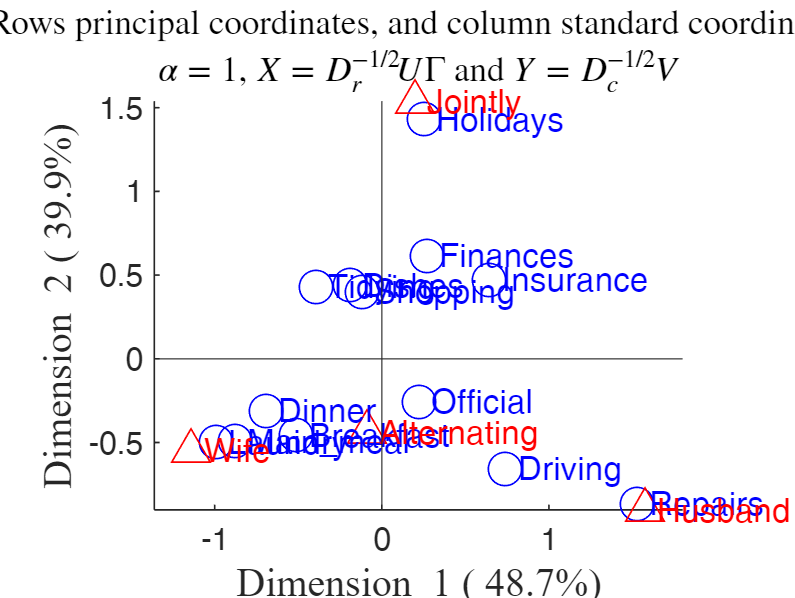

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1       0.73681        0.54289       0.48692        0.48692  
    dim_2       0.66709          0.445       0.39913        0.88605  
    dim_3       0.35644        0.12705       0.11395              1  

ROW POINTS
Results for dimension: 1
                  Scores     CntrbPnt2In    CntrbDim2In
                 ________    ___________    ___________

    Laundry      -0.99184       0.18287       0.73999  
    Main_meal    -0.87559       0.12389        0.7416  
    Dinner       -0.69257      0.054714

N=[156	14	2	4;
    124	20	5	4;
    77	11	7	13;
    82	36	15	7;
    53	11	1	57;
    32	24	4	53;
    33	23	9	55;
    12	46	23	15;
    10	51	75	3;
    13	13	21	66;
    8	1	53	77;
    0	3	160	2;
    0	1	6	153];
rowslab={'Laundry' 'Main_meal' 'Dinner' 'Breakfast' 'Tidying' 'Dishes' ...
    'Shopping' 'Official' 'Driving' 'Finances' 'Insurance'...
    'Repairs' 'Holidays'};
colslab={'Wife'	'Alternating'	'Husband'	'Jointly'};

% In this section we explore options inside input structure plots
plots.alpha='rowprincipal';

if ~verLessThan('matlab','8.3.0')
    tableN=array2table(N,'VariableNames',colslab,'RowNames',rowslab);
    out=CorAna(tableN,'plots',plots);
else
    out=CorAna(N,'Lr',rowslab,'Lc',colslab,'plots',plots);
end

## Correspondence analysis of the housetasks dataset (2)

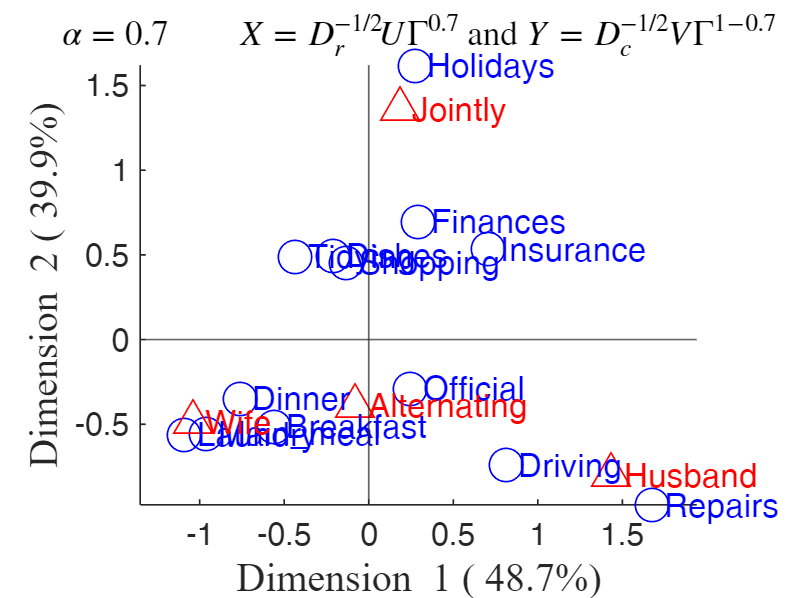

Summary
             Singular_value    Inertia    Accounted_for    Cumulative
             ______________    _______    _____________    __________

    dim_1       0.73681        0.54289       0.48692        0.48692  
    dim_2       0.66709          0.445       0.39913        0.88605  
    dim_3       0.35644        0.12705       0.11395              1  

ROW POINTS
Results for dimension: 1
                  Scores     CntrbPnt2In    CntrbDim2In
                 ________    ___________    ___________

    Laundry        -1.087       0.18287       0.73999  
    Main_meal     -0.9596       0.12389        0.7416  
    Dinner       -0.75903      0.054714

plots.alpha=0.7;
if ~verLessThan('matlab','8.3.0')
    out=CorAna(tableN,'plots',plots);
else
    out=CorAna(N,'Lr',rowslab,'Lc',colslab,'plots',plots);
end

% Compute the distance between row profiles
% \[
% d^2(row_1, row_2) = \sum{\frac{(row.profile_1 - row.profile_2)^2}{average.profile}}
% \]
% For example the distance between the rows Laundry and Main_meal is equal to:
% \[
% d^2(Laundry, Main\_meal) = \frac{(0.886-0.810)^2}{0.344} +
% \frac{(0.0795-0.131)^2}{0.146} + ... = 0.0368
% \]
disp(sum((out.ProfilesRows(1,:)-out.ProfilesRows(2,:)).^2./(out.c')))

    0.0368



% The squared distance between each row profile and the average row profile
% is given by
dist=zeros(out.I,1);
for i=1:out.I
    dist(i)=(sum((out.ProfilesRows(i,:)-out.c').^2./(out.c')));
end
% The Row inertia is calculated as the row mass multiplied by the squared
% distance between the row and the average row profile:
% \[
%     row.inertia = row.mass * d^2(row)
% \]
% Row inertia
% disp(sum(dist.*out.r))
% disp(out.TotalInertia)

## CorAna using plots as structure

Input is the contingency table, labels for rows and columns are supplied

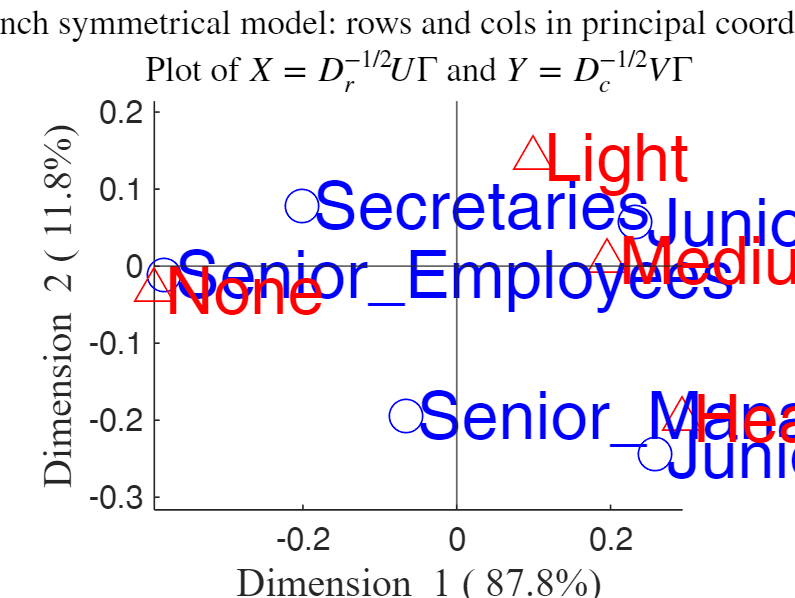

Summary
             Singular_value     Inertia      Accounted_for    Cumulative
             ______________    __________    _____________    __________

    dim_1        0.27342         0.074759        0.87756       0.87756  
    dim_2        0.10009         0.010017        0.11759       0.99515  
    dim_3       0.020337       0.00041357      0.0048547             1  

ROW POINTS
Results for dimension: 1
                         Scores      CntrbPnt2In    CntrbDim2In
                        _________    ___________    ___________

    Senior_Managers     -0.065768     0.0032977      0.092232  
    Junior_Managers       0.25896      0.083659        0.5264  
    

load('smoke')
[N,~,~,labels]=crosstab(smoke{:,1},smoke{:,2});
[I,J]=size(N);
labels_rows=labels(1:I,1);
labels_columns=labels(1:J,2);

plots=struct;
plots.FontSize=20;
out=CorAna(N,'Lr',labels_rows,'Lc',labels_columns,'plots',plots);